# Load parameters

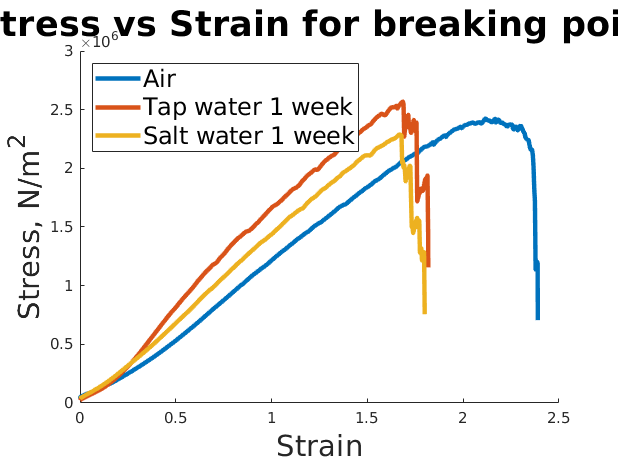

maxStress = 	1.0e+06 *

    2.4234    2.5692    2.2872


file = uigetfile('*.xlsx');
allParameters = readmatrix(file);
labels = readcell(file);
%%
[filename, filepath] = uigetfile('*.csv');
settings = {allParameters labels filename filepath};
maxStress = generateGraphs(4:6, 'Stress vs Strain for breaking point', settings)

function [stress, strain] = process(allParameters, i, filename, filepath)
    for j=1:1
        %Match pattern to dynamically read the files
        filename = regexprep(filename, '_\d+\d?+_+\d', ['_',num2str(i),'_',num2str(j)]);
        T = readmatrix([filepath filename]);
        %time = T(:,1);
        displacement = T(:,2).*1e-3; %convert to m
        force=T(:,3);
        %plotTitle=['Sample ' num2str(i)];
        %% Process Data
        % set parameters for the particular graph we're working on.
        parameters=allParameters(allParameters(:,3)==i,:);
        
        %Take dimensions from our set of parameters
        A=parameters(6)*parameters(4)*1e-6;
        L = parameters(8)*1e-3;
        stress=force/A;
        strain=displacement/L;
    end
end

function makePlot(x, y, makeTitle)
    plot(x,y, 'linewidth',3)
%     axis([0 inf 0 inf])
    xlabel('Strain', 'FontSize', 20); ylabel('Stress, N/m^2', 'FontSize', 20);
    title(makeTitle, 'FontSize', 24);
end
function maxStress = generateGraphs(i, plotTitle, settings)
    [allParameters, alllabels, filename, filepath] = settings{1:4};
    alllabels = string(alllabels(2:end,2:3));
    labels=[];
    figure; hold on;
    maxStress = [];
    for i = i
        labels = [labels alllabels(str2double(alllabels(:,2))==i,1)]; %dynamically generate labels
        [stress, strain] = process(allParameters,i, filename, filepath);
        maxStress = [maxStress max(stress)];
        makePlot(strain, stress, plotTitle);
    end
%     legend(labels, 'Location', "northwest")
legend('Air', 'Tap water 1 week', 'Salt water 1 week', 'Location', "northwest", 'FontSize', 16)
    hold off 
end